# Nonlocal Cahn–Hilliard with a constant source

Here we will test the Multi Shape-based Singular Kernel that we have obtained so far to solve an NCH system with a source. The source is such that we should be able to, at least numerically, consider its generator as an exact solution. We will provide more insights on this later on.

## Initialisation

First we define the spectral box for spatial discretisation and a spectral line for time evaluation. The spectral box will be loaded from the pre assembled Singular Kernel dataset.

% Load a SK: 10 × 10 box with 𝜀 = 10^-2
load('Singular_Kernels_Subs_20_epsA.mat', 'Newtonians')
Newtonians

Newtonians = struct with fields:
        I: @Conv_I
        J: @Conv_J
        G: @Conv_G
       NJ: [400×1 double]
       NG: [400×1 double]
       NI: [400×1 double]
      eps: 0.010000000000000
      box: [1×1 Box]
        N: 20
    Level: [1×1 struct]



% Retrieve box and number of collocation points
aBox     = Newtonians.box;          % This is the domain
[N1, N2] = deal(aBox.N1, aBox.N2);
epsilon  = Newtonians.eps;          % This is ε

For the selected box and value of $\varepsilon ,$ we select a convolution matrix based on a subdivision factor:

Newtonians.Level.Available          % Check available matrices

ans =      1     5     8


% Select convolution matrix
Conv = Newtonians.Level.n2;         % Name format: 'n' + factor
% Retrieve additional data
Conv_D = Newtonians.NG;

Define additional structures in the box for defining the differential equation:

% Points, differentiation matrices, integration vector, and indices
% giving masks for the boundary
[Pts,Diff,Int,Ind] = aBox.ComputeAll();    
grad  = Diff.grad;       div = Diff.div;
bound = Ind.bound;    normal = Ind.normal;
Lap_Space = Diff.Lap;

% compute the interpolation matrix from the box points to a uniform
% grid [only for plotting]
Interp = aBox.ComputeInterpolationMatrix(...
                             (-1:0.02:1)',(-1:0.02:1)',true,true);

## Exact solution

Now we perform the following construction: Let $\tilde{\varphi} \left(x;t\right)=\frac{1}{2}$, $\tilde{\mu} =\log \left(3\right)-\frac{1}{2}K\ast 1$, $\tilde{g} \left(x\right)=0-\Delta_x \tilde{\mu} \left(x\right)$. Here the function $F$ is given by $F\left(s\right)=\left(1+s\right)\;\log \left(1+s\right)+\left(1-s\right)\;\log \left(1-s\right)$ and $F^{\prime } \left(s\right)=\log \left(1+s\right)-\log \left(1-s\right)$. 

First, let's define the initial condition $\rho_0 \left(x\right)=\frac{1}{2}$:

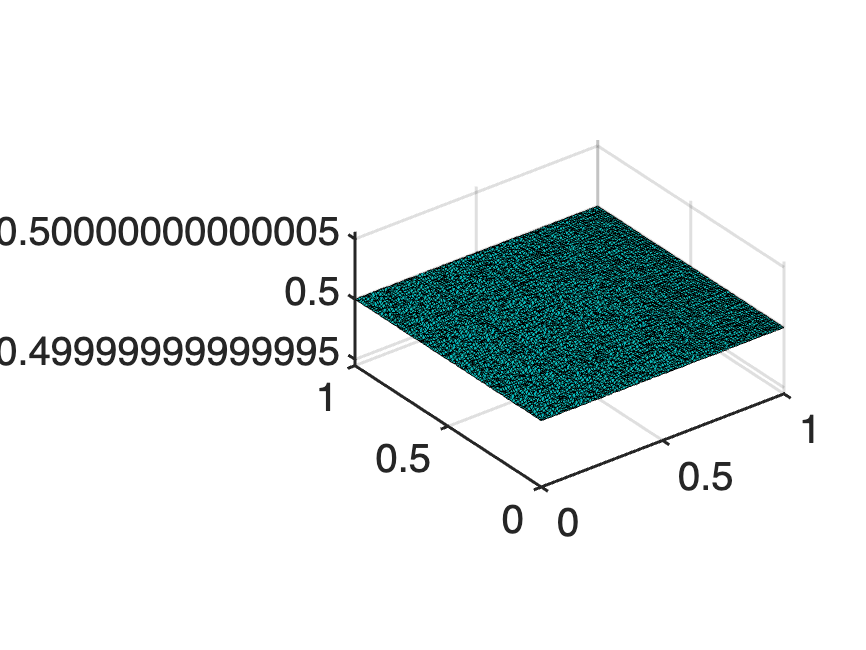

phi_ic = 0.5 * ones( size(Pts.y1_kv) );
aBox.plot(phi_ic, {});
xlabel(''); ylabel(''); zlabel('');

Now let's compute a discretised version of $\tilde{\varphi} \left(x\right)$, for this we also discretise the interval $\left\lbrack 0,T_{\max } \right\rbrack$ noticing that we can properly define $F^{\prime } \left(\tilde{\varphi} \right)$ everywhere:

% Time collocation points
tMax = 1.0; % Usually T = 50
n_t  = 100;   % often 100
% Set up a time line where we are currently at 
ge.yMin  = 0.0;    ge.yMax = tMax;    ge.N = n_t;
TimeLine = SpectralLine(ge);
outTimes = TimeLine.Pts.y;
TimeLine.ComputeDifferentiationMatrix;
D_Time = TimeLine.Diff.Dy;

% Now combine
phi = ones([n_t,1]) * phi_ic';

Let's visualise $F\left(s\right)$ and its first two derivatives:

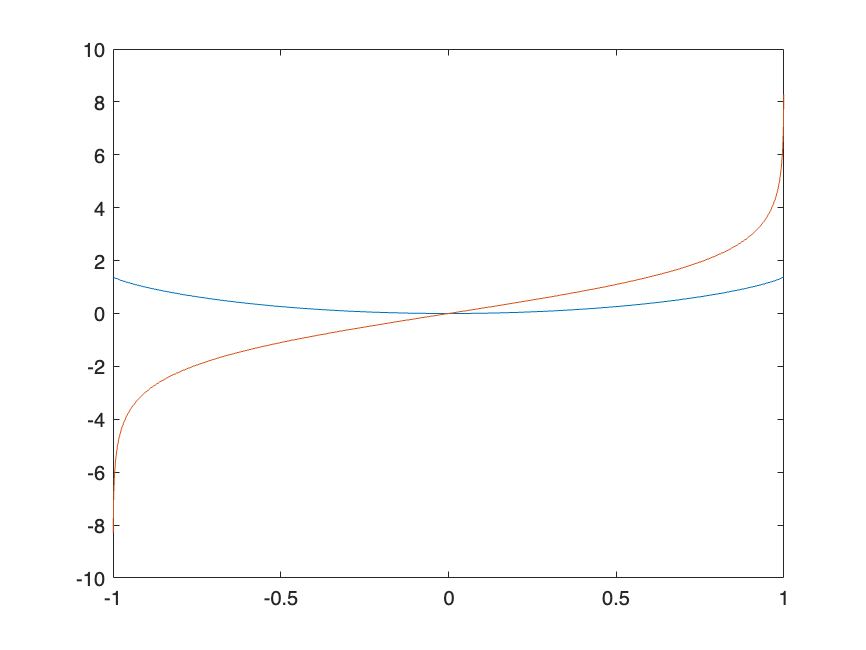

F  = @(s) (1+s) .* log(1+s) + (1-s) .* log(1-s);
dF = @(s) log(1+s) - log(1-s);
ddF = @(s) -2 ./ ( 1 - s.^2 );

plot(TimeLine.Pts.x,  F(TimeLine.Pts.x));    hold on
plot(TimeLine.Pts.x, dF(TimeLine.Pts.x));   hold off

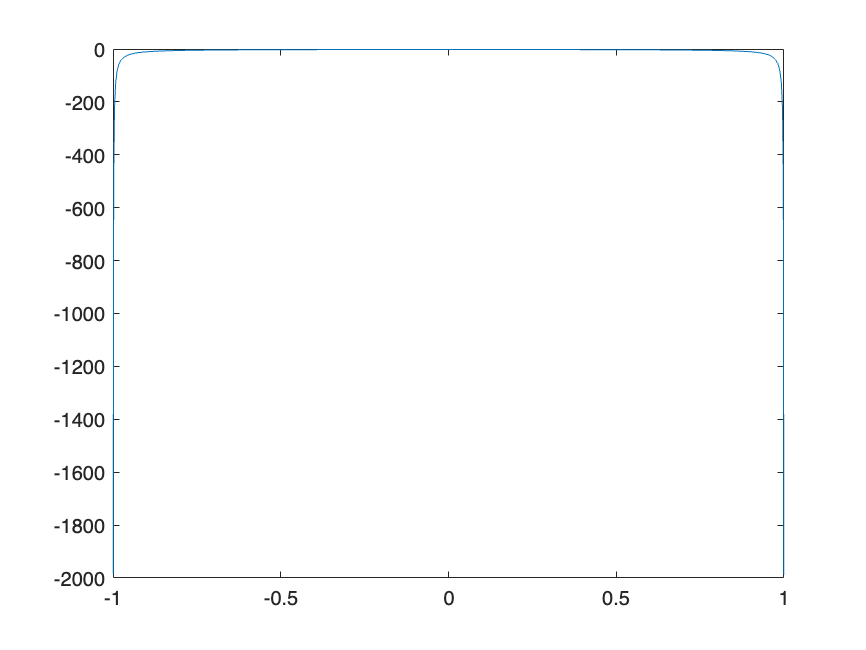

plot(TimeLine.Pts.x, ddF(TimeLine.Pts.x));   hold off

Now we can evaluate $\tilde{\mu} \left(x\right)$ and its Laplacian:

mu_tilde = dF(phi_ic);
mu_tilde = mu_tilde - 0.5 * Newtonians.J([Pts.y1_kv,Pts.y2_kv]);
%mu_tilde = mu_tilde - (Conv * phi' + Conv_D .* phi')';
g_tilde = 0.5; % * ones(size(mu_tilde)); % -(Lap_Space * mu_tilde')' ;   (0.5 except at corners)
%dnsigma = normal * (grad * mu_tilde);
dnsigma = (-0.5) * normal * ( Newtonian_Grad_IJ([Pts.y1_kv,Pts.y2_kv]).dJ );

## Differential system

We aim to solve the following system:


$$\begin{array}{rcl}
\varphi_t - \Delta \mu &=& \tilde{g}
\\
\mu &=& F'(\varphi) - K\star \varphi
\\
\partial_n \mu &=& \partial_n \tilde{\mu}
\\
\varphi(x;0) &=& \varphi_0 
\end{array}$$


To do this we will use a differential equation solver and the following functions:

Phi_t = NL_CH_Integrator_Source_Constant(phi_ic,  aBox, Diff, Ind,  Conv, ...
                            Conv_D, dF, ddF, g_tilde, dnsigma, TimeLine, 0.0 );

93 successful steps
9 failed attempts
1793 function evaluations
4 partial derivatives
28 LU decompositions
189 solutions of linear systems
Elapsed time is 0.730076 seconds.


We can check that energy has been preserved:

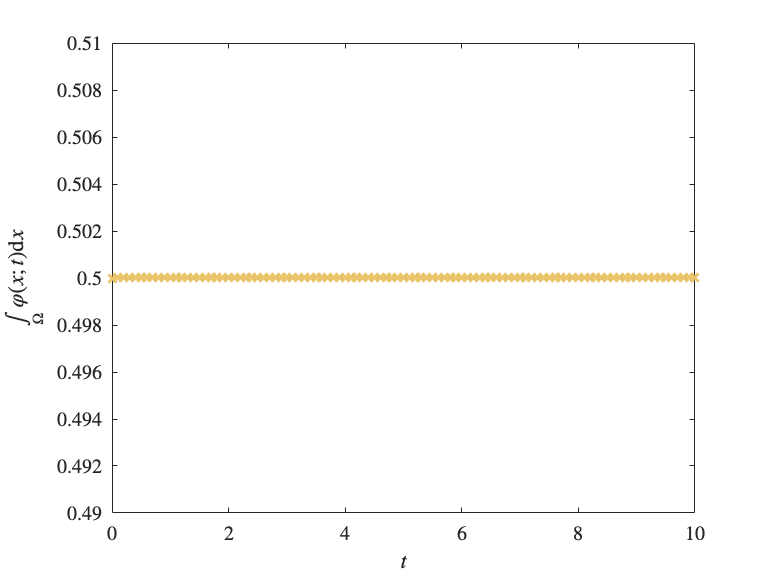

Time_Span_ODE = outTimes; %[0: outTimes(end)/100: outTimes(end)];

Mass_Time = Int * Phi_t';
figure(1)
plot(Time_Span_ODE, Mass_Time, 'LineWidth', 1.5, 'Color', ...
    '#e9c46a', 'LineStyle', '-', 'Marker','x')
ylim([0.49,0.51])

xlabel('$t$','Interpreter','latex'); 
ylabel( strcat(['$\int\limits_\Omega \varphi(x;t) ', ...
    '\mathrm{d}x $']), ...
    'Interpreter','latex');
set(gca, 'TickLabelInterpreter', 'latex');

% exportgraphics(figure(1), 'NLCH_Diffusion_Test_Mass.pdf', ...
%     'BackgroundColor','none', 'ContentType', 'vector', 'Resolution', 300)
hold off

Let us compute the error:

% Phi_e = Phi_t * 0.0;
% 
% k = 1;
% for t = Time_Span_ODE'
%     %IP_Time = TimeLine.ComputeInterpolationMatrixPhys(t).InterPol;
%     if t == 0.0
%         Phi_e(k,:) = phi_ic';
%     else
%         Phi_e(k,:) = exp(-t) * phi_ic'; %IP_Time * phi;
%     end
%     k = k + 1;
% end
Phi_e = exp(-0.0) * phi_ic';

Now we can plot the solution:

%plots_in_box(Phi_t, aBox, Time_Span_ODE)

The error:

%plots_in_box(Phi_e - Phi_t, aBox, Time_Span_ODE,  ...
% 'NLCH_Diffusion_Test_Error.gif', '$e(x;t)$')

And the evolution of the $\ell_2$ error in time:

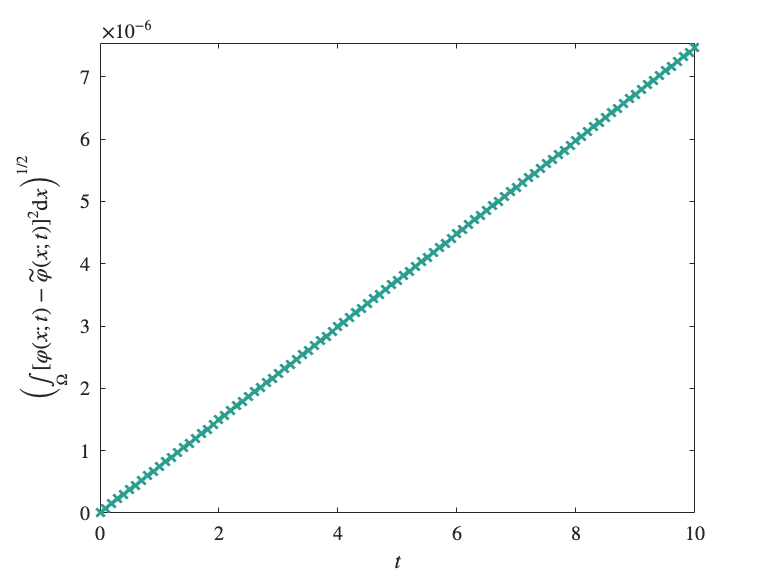

Err_Int = (Int * ((Phi_t - 0.5)'.^2)).^0.5;

figure(3)
plot(Time_Span_ODE, Err_Int, 'LineWidth', 1.5, 'Color', ...
    '#2a9d8f', 'LineStyle', '-', 'Marker','x')
ylim([0,max(Err_Int)*1.01])

xlabel('$t$','Interpreter','latex'); 
ylabel( strcat(['$\left( \int\limits_\Omega [\varphi(x;t) ', ...
    '- \tilde{\varphi}(x;t)]^2 \mathrm{d}x \right)^{1/2} $']), ...
    'Interpreter','latex');
set(gca, 'TickLabelInterpreter', 'latex');


% exportgraphics(figure(3), 'NLCH_Diffusion_Test_Error_l2.pdf', ...
%     'BackgroundColor','none', 'ContentType', 'vector', 'Resolution', 300)

% To evaluate error at end run: Err_Int(end)